# Prácticas de Control por Computador (3º GIERM, UMA)

## Práctica 5: Diseño de controladores PID en Matlab

#### **Tarea 1: Análisis respuesta temporal de control P, PI**

La gráfica muestra un sistema compuesto por un *proceso* a controlar usando un controlador digital, mediante la realimentación proporcionada por un *sensor digital*.

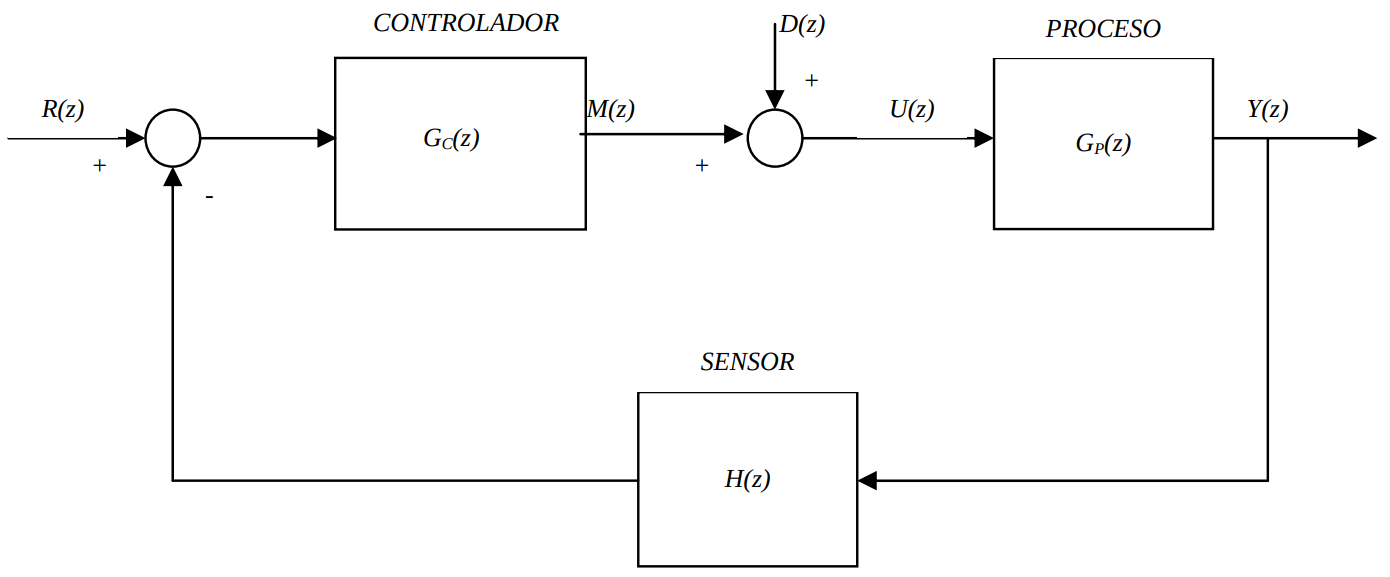

Si las funciones de transferencia del proceso continuo y el sensor continuo originales son $G_p \left(s\right)=\frac{4}{\left(2s+1\right)\left(0\ldotp 5s+1\right)}$ y $H\left(s\right)=\frac{1}{0\ldotp 05s+1}$ y el tiempo de muestreo es de $T=0\ldotp 1s$.

 **a.** Obtener graficamente la respuesta en bucle abierto $G_p \left(z\right)H\left(z\right)$del sistema, ante una entrada en escalón, discretizando la planta y sensor con el metodo 'zoh' (suponer que se realiza un muestreo entre el proceso y el sensor). ¿Qué valores toman el tiempo de subida $T_r$, el tiempo de establecimiento $T_s$, el valor en estado estacionario $Y_{\textrm{ss}}$y el maximo impulso porcentual $M_p$? (usar `step` y `stepinfo`).

% Tu código aquí
T = 0.1;
s = tf('s');
Gp = 4/((2*s+1)*(0.5*s+1))

Gp =
 
         4
  ---------------
  s^2 + 2.5 s + 1
 
Continuous-time transfer function.
Model Properties


H = 1/(0.05*s+1)

H =
 
      1
  ----------
  0.05 s + 1
 
Continuous-time transfer function.
Model Properties


Gpz = c2d(Gp,T,'zoh')

Gpz =
 
   0.01842 z + 0.01695
  ---------------------
  z^2 - 1.77 z + 0.7788
 
Sample time: 0.1 seconds
Discrete-time transfer function.
Model Properties


Hz = c2d(H,T,'zoh')

Hz =
 
    0.8647
  ----------
  z - 0.1353
 
Sample time: 0.1 seconds
Discrete-time transfer function.
Model Properties


Gba = Gpz*Hz

Gba =
 
         0.01592 z + 0.01465
  ----------------------------------
  z^3 - 1.905 z^2 + 1.018 z - 0.1054
 
Sample time: 0.1 seconds
Discrete-time transfer function.
Model Properties


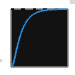

step(Gba)

stepinfo(Gba)

ans = struct with fields:
         RiseTime: 4.6000
    TransientTime: 8.6000
     SettlingTime: 8.6000
      SettlingMin: 3.6007
      SettlingMax: 3.9980
        Overshoot: 0
       Undershoot: 0
             Peak: 3.9980
         PeakTime: 15.9000


`Resultado esperado:`

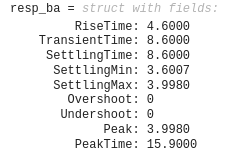

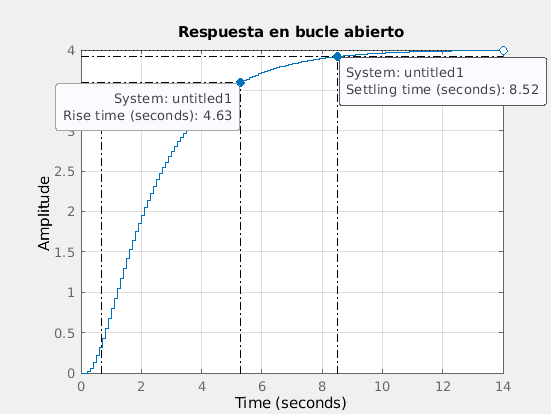

 **b.** Diseñar un controlador P digital, con valores $K_p$=0.7, 1.2 y 1.7. Obtener todas las gráficas del sistema con el controlador, ante una entrada escalón, en una misma representación gráfica evaluando el tiempo de subida $T_r$, el tiempo de establecimiento $T_s$, el error en estado estacionario $E_{\textrm{ss}}$y el maximo impulso porcentual $M_p$. ¿Qué cambios se observan conforme aumenta $K_p$, en los cuatro parámetros analizados anteriormente?.

% Tu código aquí
Kp1 = 0.7;
Kp2 = 1.2;
Kp3 = 1.7;

PID1 = pid(Kp1,0,0,0,T,'Iformula','Trapezoidal');
PID2 = pid(Kp2,0,0,0,T,'Iformula','Trapezoidal');
PID3 = pid(Kp3,0,0,0,T,'Iformula','Trapezoidal');
Gbcz1 = feedback(PID1*Gpz,Hz)

Gbcz1 =
 
  0.01289 z^2 + 0.01012 z - 0.001605
  -----------------------------------
  z^3 - 1.905 z^2 + 1.029 z - 0.09514
 
Sample time: 0.1 seconds
Discrete-time transfer function.
Model Properties


Gbcz2 = feedback(PID2*Gpz,Hz)

Gbcz2 =
 
   0.0221 z^2 + 0.01734 z - 0.002752
  -----------------------------------
  z^3 - 1.905 z^2 + 1.037 z - 0.08782
 
Sample time: 0.1 seconds
Discrete-time transfer function.
Model Properties


Gbcz3 = feedback(PID3*Gpz,Hz)

Gbcz3 =
 
  0.03131 z^2 + 0.02457 z - 0.003899
  -----------------------------------
  z^3 - 1.905 z^2 + 1.045 z - 0.08049
 
Sample time: 0.1 seconds
Discrete-time transfer function.
Model Properties


resp_k07 = stepinfo(Gbcz1);
resp_k12 = stepinfo(Gbcz2);
resp_k17 = stepinfo(Gbcz3);
resp_k07,resp_k12,resp_k17

resp_k07 = struct with fields:
         RiseTime: 0.9000
    TransientTime: 4.2000
     SettlingTime: 4.2000
      SettlingMin: 0.6992
      SettlingMax: 0.8495
        Overshoot: 15.2876
       Undershoot: 0
             Peak: 0.8495
         PeakTime: 1.9000


resp_k12 = struct with fields:
         RiseTime: 0.5000
    TransientTime: 4.8000
     SettlingTime: 4.8000
      SettlingMin: 0.7462
      SettlingMax: 1.0863
        Overshoot: 31.2600
       Undershoot: 0
             Peak: 1.0863
         PeakTime: 1.4000


resp_k17 = struct with fields:
         RiseTime: 0.5000
    TransientTime: 5.4000
     SettlingTime: 5.4000
      SettlingMin: 0.6905
      SettlingMax: 1.2704
        Overshoot: 45.7226
       Undershoot: 0
             Peak: 1.2704
         PeakTime: 1.2000


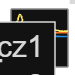

step(Gbcz1,Gbcz2,Gbcz3)
legend('Gbcz1','Gbcz2','Gbcz3')

`Resultado esperado:`

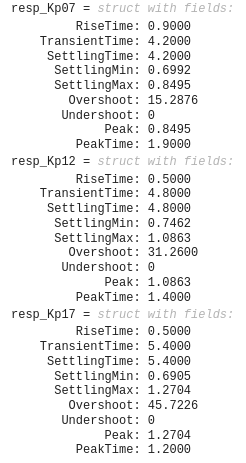

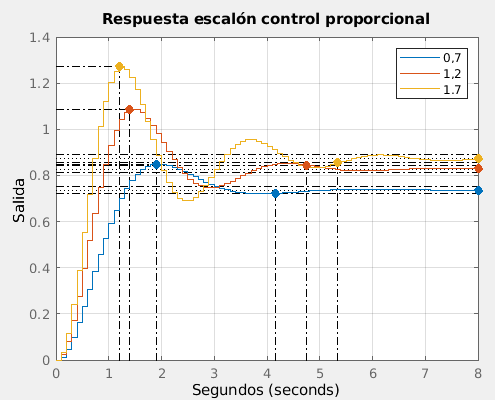

 **c.** Sustituir el controlador P digital por un controlador PI digital, obtenido a partir de la discretización trapezoidal del PI continuo, con un valor fijo de $K_p =1\ldotp 7$y $K_i$tomando valores 0.25 y 0.5. Obtener todas las gráficas de las respuesta del sistema con el controlador, ante una entrada escalón. ¿Qué cambios se observan ahora, conforme aumenta  $K_i$, en los parámetros?.

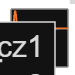

% Tu código aquí
Kp = 1.7;
Ki1 = 0.25;
Ki2 = 0.5;
PID1 = pid(Kp,Ki1,0,0,T,'Iformula','Trapezoidal'); 
PID2 = pid(Kp,Ki2,0,0,T,'Iformula','Trapezoidal');
Gbcz1 = feedback(PID1*Gpz,Hz);
Gbcz2 = feedback(PID2*Gpz,Hz);
step(Gbcz1,Gbcz2)
legend('Gbcz1','Gbcz2')

`Resultado esperado:`

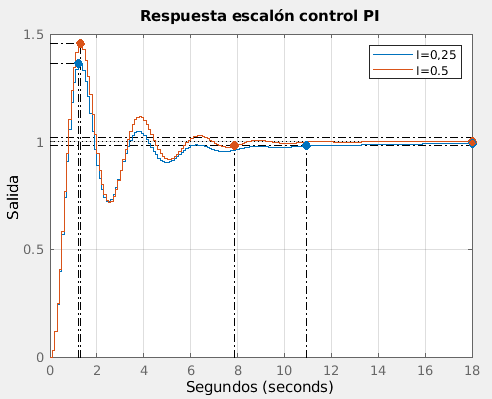

#### Tarea 2: Analisis de control PID

El sistema de control de la figura muestra un control de velocidad PID (proporcional + integral + derivativo) que actia sobre un motor de corriente contínua, con función de transferencia


$$G_p \left(s\right)=\frac{0\ldotp 01}{0\ldotp 005s^2 +0\ldotp 06s+0\ldotp 1001}$$


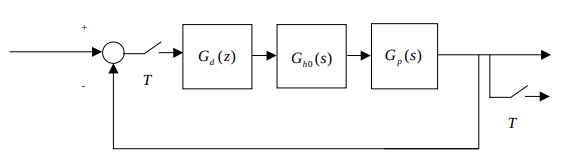

El controlador PID viene dado por


$$G_d \left(s\right)=K_p +\frac{K_i }{s}+K_d s=\frac{K_d s^2 +K_p s+K_i }{s}$$


con valores variables de $K_p$, $K_i$y$K_d$.

Representar gráficamente de forma simultanea la respuesta escalón en bucle cerrado del sistema de control con el PID discretizado:

- Con $K_p$=50, $K_i =K_d =0$.

- Con $K_p$=50, $K_i$=20 y $K_d =0$.

- Con $K_p$=50, $K_i$=20 y $K_d =5$.

aplicando el metodo de discretización trapezoidal (transformacion bilineal) para el PID, con un tiempo de muestreo $T$=0.01.

% Tu código aquí
T = 0.01; K = 0.01;
Gp = tf([1],[0.005 0.06 0.1001]);
Gp = K*Gp

Gp =
 
             0.01
  ---------------------------
  0.005 s^2 + 0.06 s + 0.1001
 
Continuous-time transfer function.
Model Properties


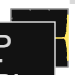

PID1 = pid(50,0,0,0,T,'Iformula','Trapezoidal');
PID2 = pid(50,20,0,0,T,'Iformula','Trapezoidal');
PID3c = pid(50,20,5,0,'Iformula','Trapezoidal');
PID3 = c2d(PID3c,T,'Tustin');
Gpz = c2d(Gp,T,'zoh');
Gpbcz1 = feedback(PID1*Gpz,1);
Gpbcz2 = feedback(PID2*Gpz,1);
Gpbcz3 = feedback(PID3*Gpz,1);
step(Gpbcz1,Gpbcz2,Gpbcz3)
legend('P','PI','PID')

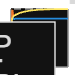

%Ahora estudio la respuesta en continuo
PID1c = d2c(PID1,'Tustin');
PID2c = d2c(PID2,'Tustin');
PID3c;
Gbc1 = feedback(PID1c*Gp,1);
Gbc2 = feedback(PID2c*Gp,1);
Gbc3 = feedback(PID3c*Gp,1);
step(Gbc1,Gbc2,Gbc3)
legend('P','PI','PID')

`Resultado esperado:`

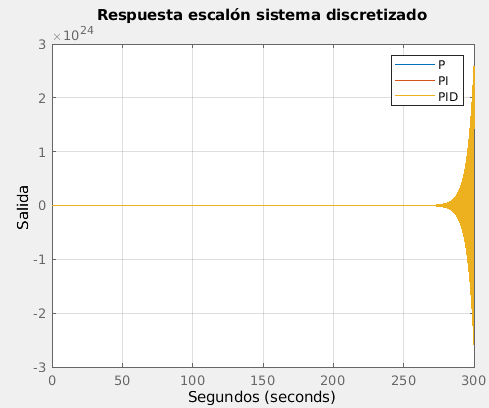

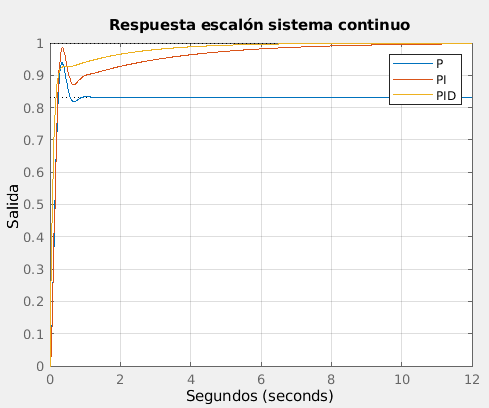

#### Tarea 3: Diseño de compensador PID en tiempo discreto

Considerese el sistema definido por su función de transferencia:


$$G\left(s\right)=\frac{1}{s^2 +18s+90}$$


compensada en tiempo discreto con una ganancia *K* variable.

**a.** Discretizar el sistema con *T*=0.1 y trazar el lugar de las raices del sistema contínuo original y del sistema discretizado y compararlo.

% Tu código aquí
T = 0.1;
G = tf([1],[1 18 90]);
Gz = c2d(G,T,'zoh')

Gz =
 
   0.00279 z + 0.001526
  -----------------------
  z^2 - 0.7768 z + 0.1653
 
Sample time: 0.1 seconds
Discrete-time transfer function.
Model Properties


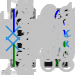

subplot(1,2,1)
rlocus(G)
sgrid 

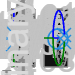

subplot(1,2,2)
rlocus(Gz)
sgrid

`Resultado esperado:`

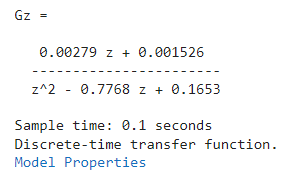

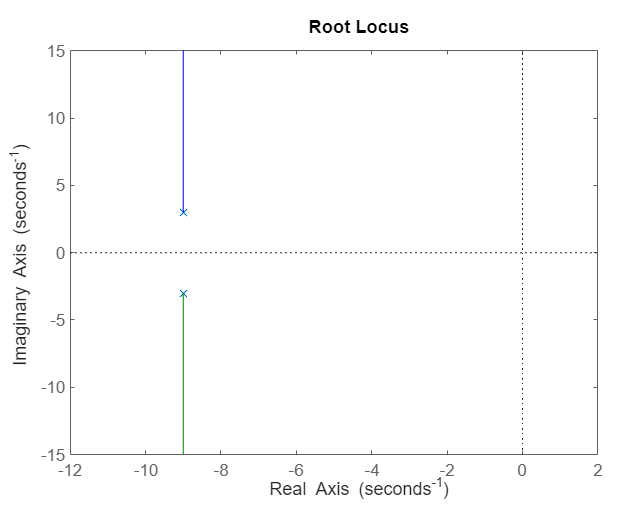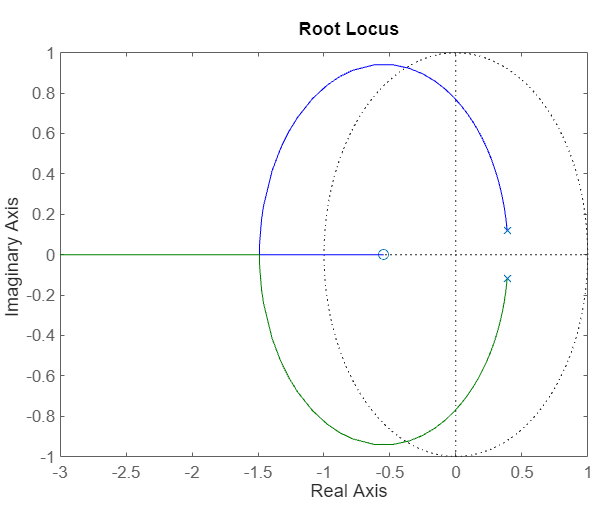

**b.** Hallar mediante el lugar de las raices discreto con rltool, el valor de *K* para que el sistema en bucle cerrado en tiempo discreto presente un sobreoscilación máxima porcentual$M_p$ inferior al 5%, un tiempo de establecimiento menor de 1s y con **error en régimen permanente mínimo ante una entrada tipo escalón**.

% Tu código aquí
rltool(Gz)

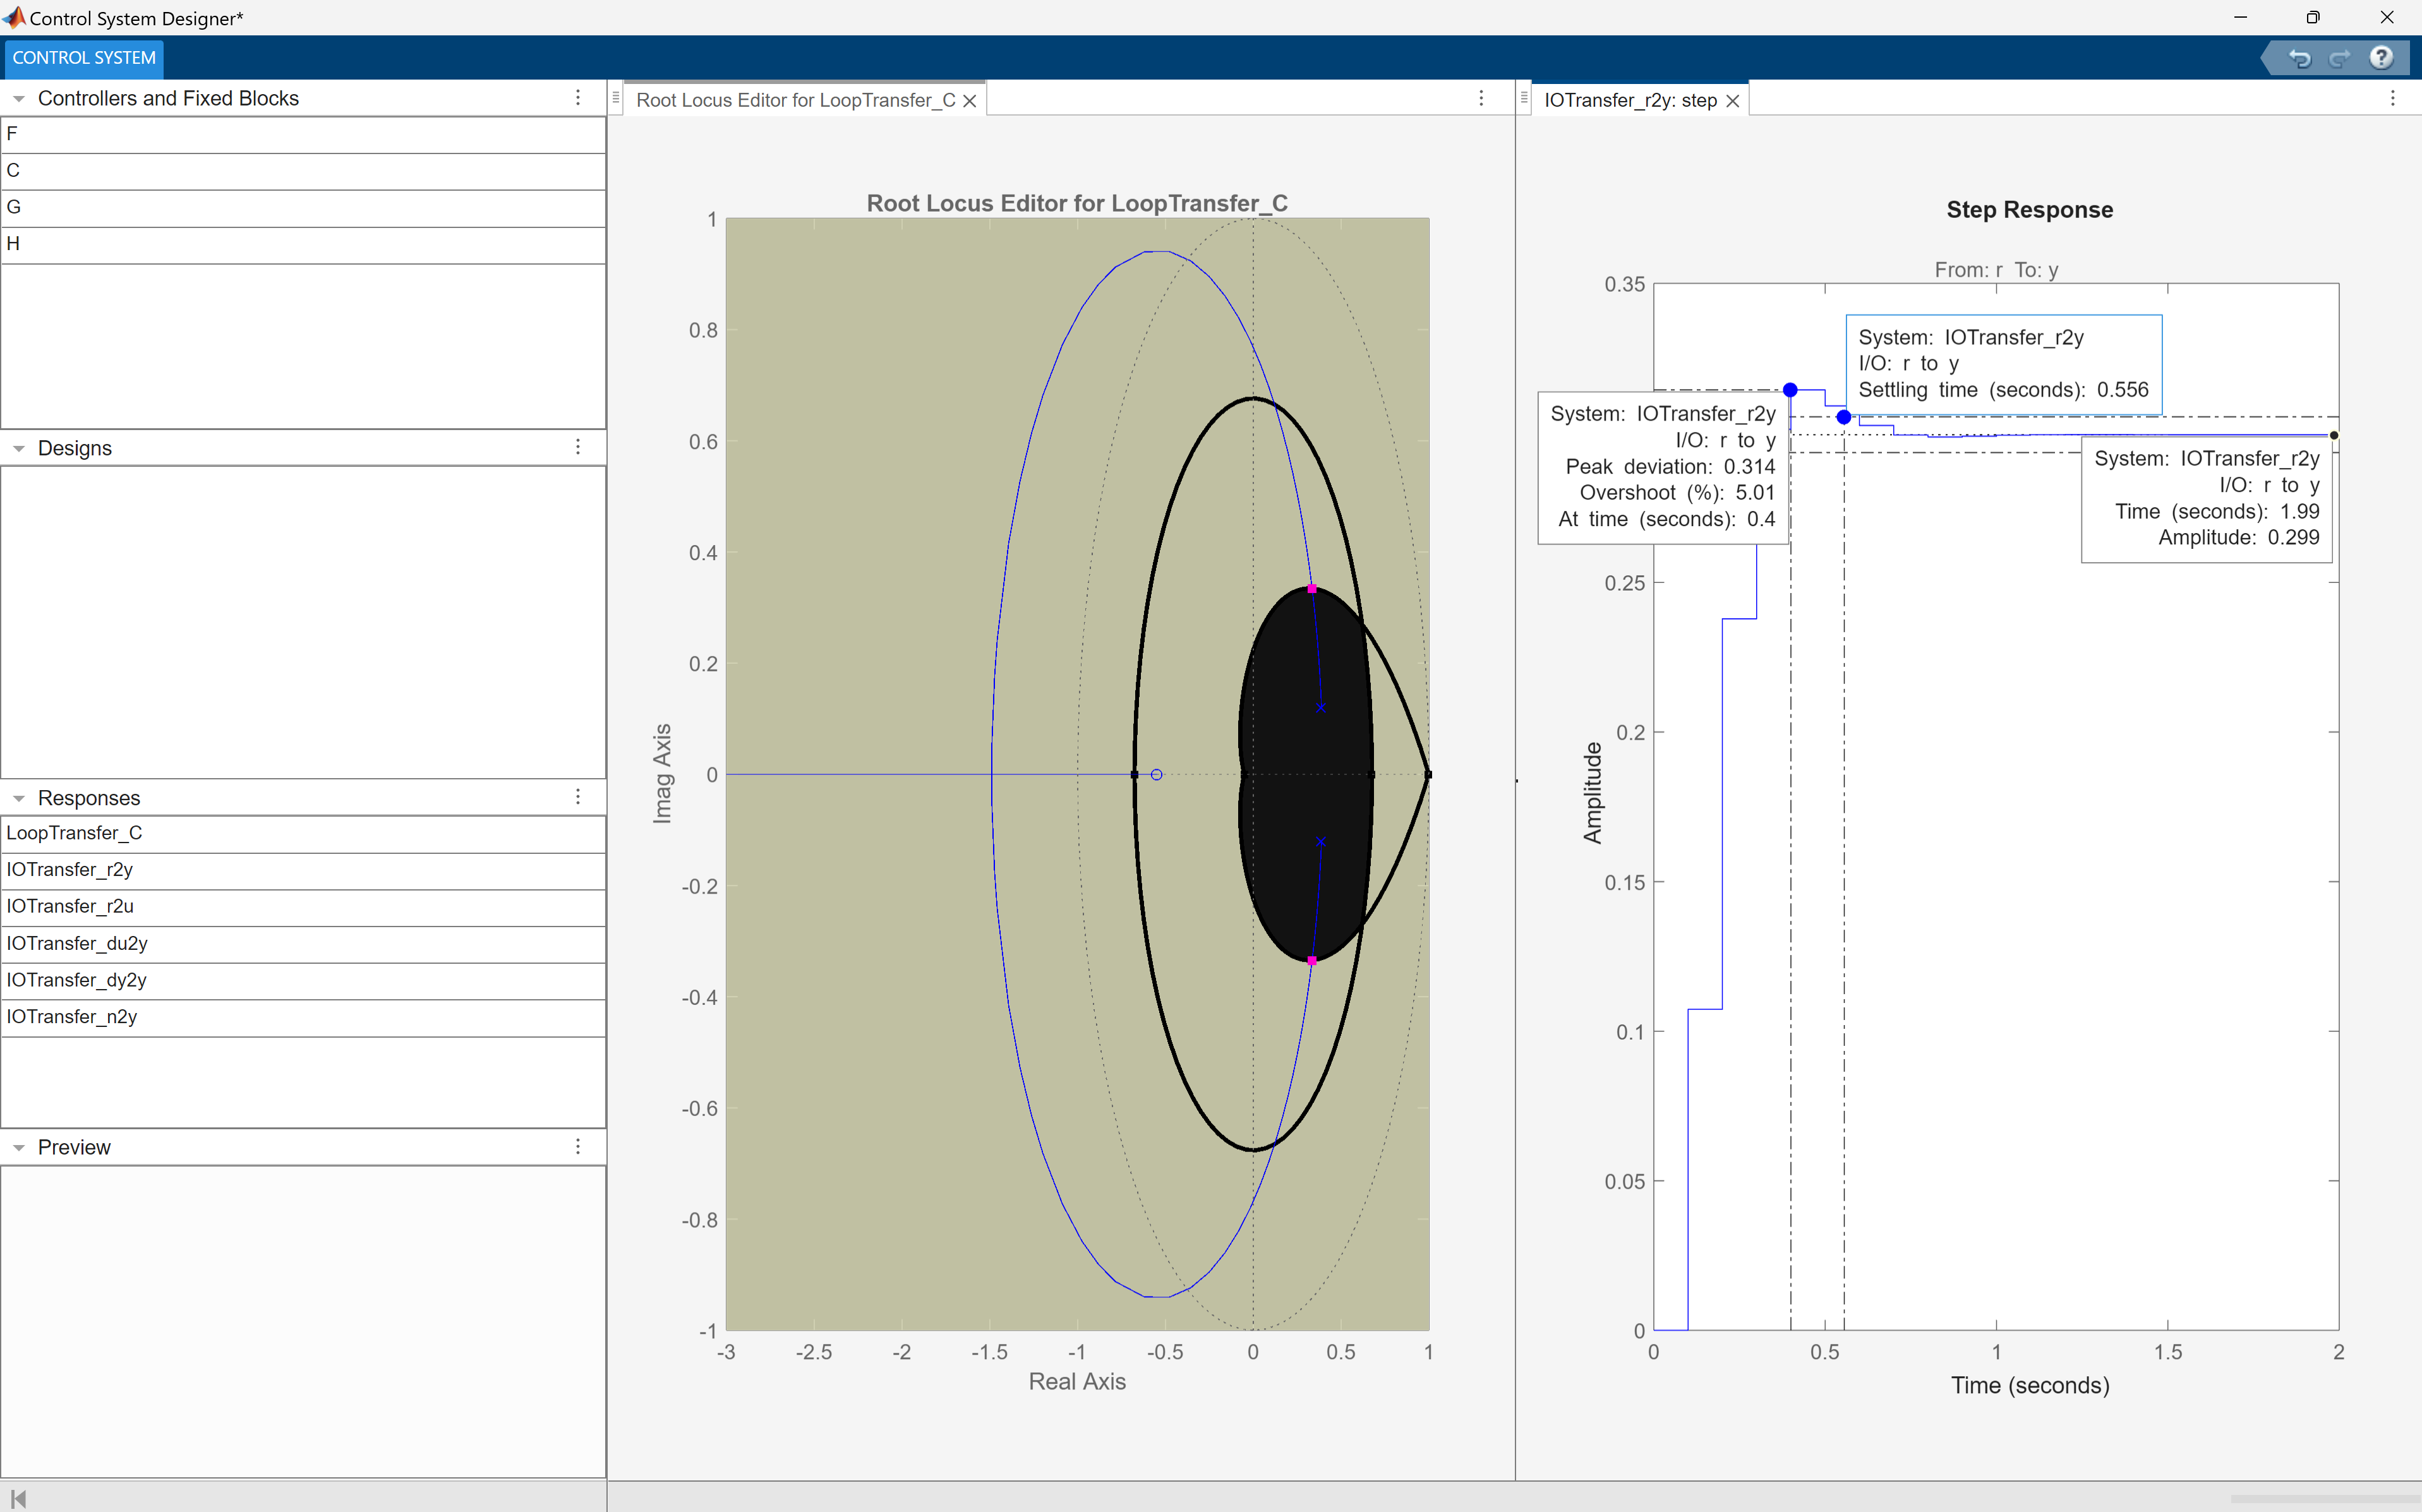

`Resultado esperado:`

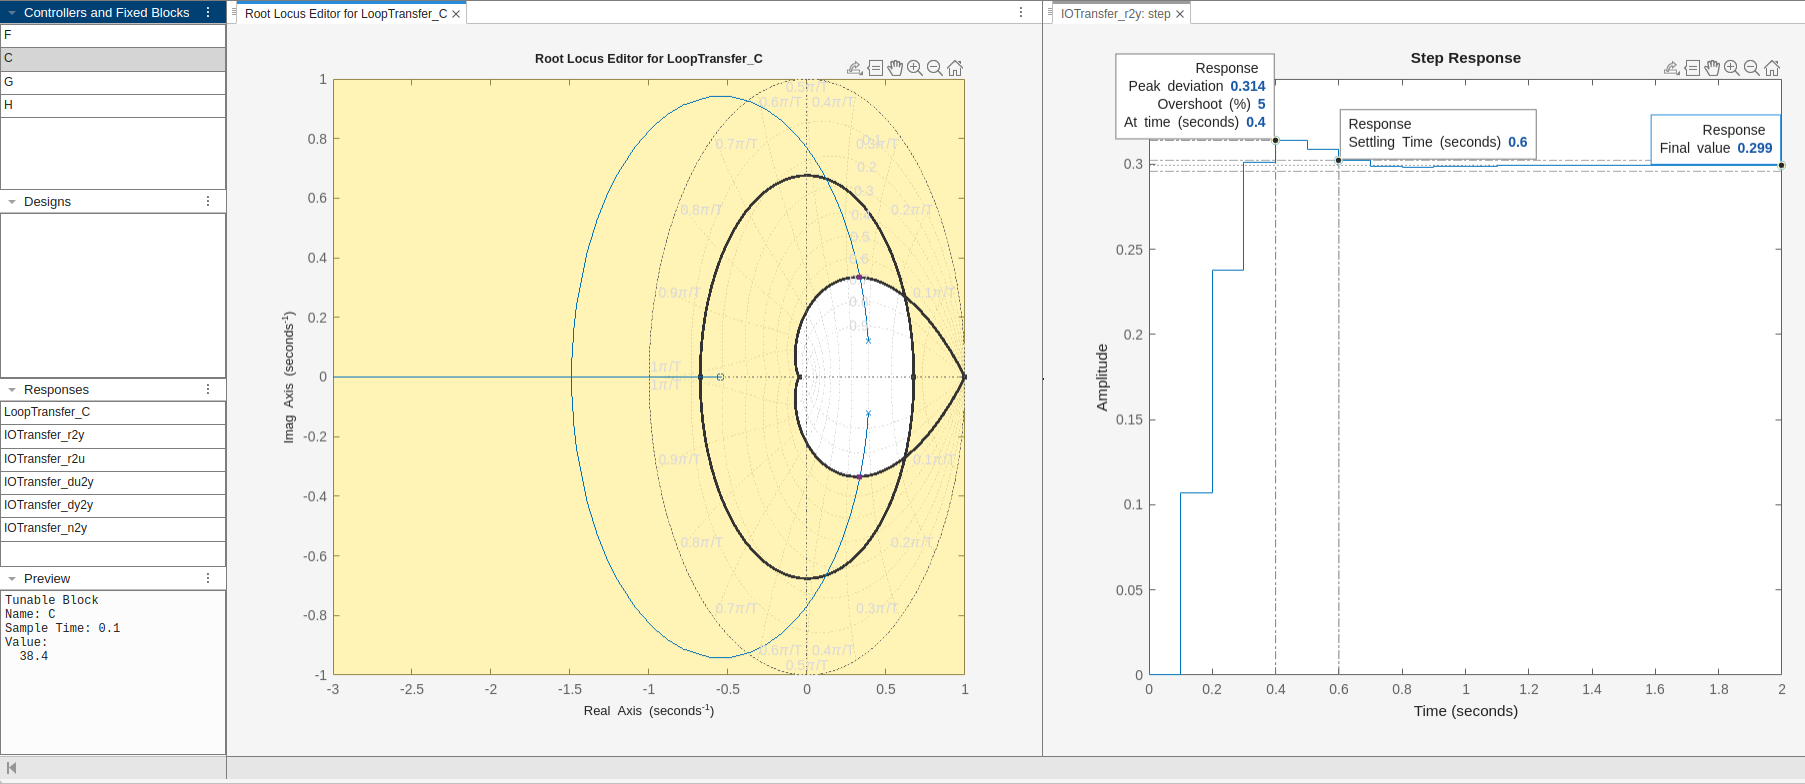

**c.**  Hallar directamente en el plano z un compensador digital tipo PI, PD o PID para que el sistema en bucle cerrado en tiempo discreto presente una sobreoscilación máxima $M_p$ inferior al 5%, un tiempo de establecimiento menor de 1s y con error de segumiento para una entrada escalón nulo. Razonar la solución.

% Tu código aquí
rltool(Gz)

`Resultado esperado:`